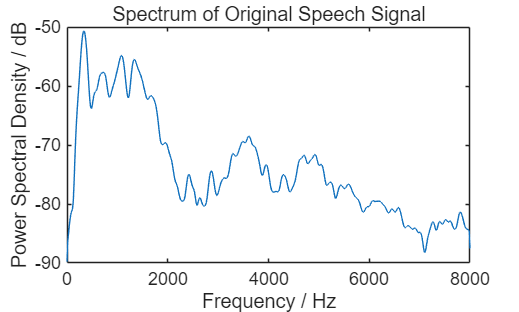

[y,fs1]=audioread("C:\Users\18237\Desktop\C_01_01(1).wav");

x=y';
window=hamming(256);
overlap=128;
NFFT=1024;
fs=16000;
[Pxx1,w]=pwelch(x,window,overlap,NFFT,fs);
figure;
plot(w,10*log10(Pxx1));
xlabel('Frequency / Hz');
ylabel('Power Spectral Density / dB');
title('Spectrum of Original Speech Signal');

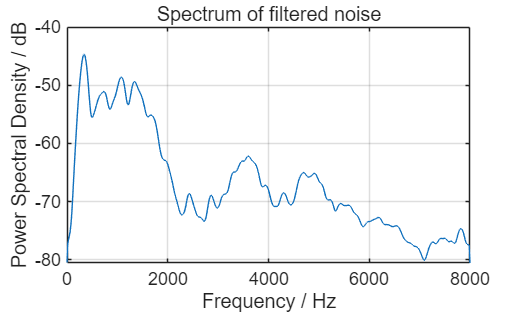

b=fir2(3000,w/(fs/2),sqrt(Pxx1/max(Pxx1)));
[h,wh]=freqz(b,1,128);
noise=1-2*rand(1,length(x));
ssn=filter(b,1,noise);
[Pss, ws] = pwelch(ssn, window, overlap, NFFT, fs);
figure;
plot(ws, 10*log10(Pss));
grid on;
xlabel('Frequency / Hz');
ylabel('Power Spectral Density / dB');
title('Spectrum of filtered noise');

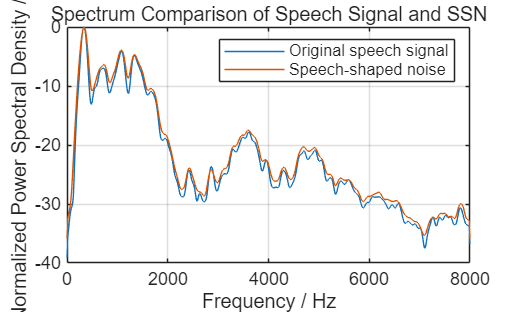

figure;
plot(w,10*log10(Pxx1/max(Pxx1)));
hold on;
plot(ws,10*log10(Pss/max(Pss)));
grid on;
xlabel('Frequency / Hz');
ylabel('Normalized Power Spectral Density / dB');
title('Spectrum Comparison of Speech Signal and SSN');
legend('Original speech signal','Speech-shaped noise');

snr=-5;
ssn=ssn/norm(ssn)*(norm(x)/(10^(snr/20)));
y0=x+ssn;
y=y0/norm(y0)*norm(x);
snr_check=20*log10(norm(x)/norm(ssn));
disp(snr_check);

    -5



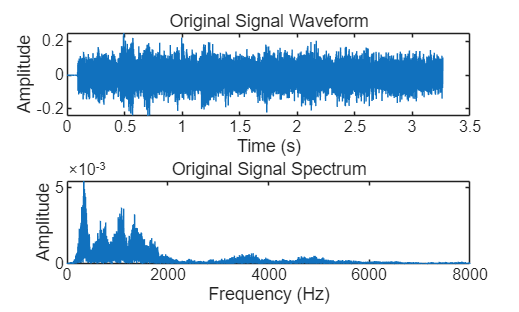

L = length(y);
t = (0:L-1) / fs; 
f = fs * (0:(L/2)) / L; 

N = 6;
pass_band_lower = 200 : (7000-200)/6 : 7000-(7000-200)/6;
pass_band_upper = 200+(7000-200)/6 : (7000-200)/6 : 7000;
center_freq = (pass_band_lower + pass_band_upper) / 2;


figure('Name', 'Noisy Signal (SNR=-5dB)');
subplot(2,1,1);
plot(t, y);
title('Noisy Signal Waveform (SNR = -5dB)');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y);
P1 = abs(Y_fft/L); P_single = P1(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title('Noisy Signal Spectrum');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

LPF_cut_freq = 20

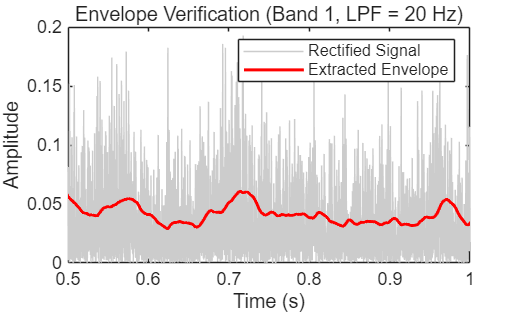


LPF_cut_freq = 20;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2));

y_sum = zeros(1, length(y));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y_band = filter(B, A, y);
    y_band_abs = abs(y_band);
    y_envelope = filter(b0, a0, y_band_abs);

    if i == 1 
        figure;
        plot(t, y_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (Band 1, LPF = %d Hz)', LPF_cut_freq));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t); 
    y_modulated = y_envelope .* sine_wave;
    y_sum = y_sum + y_modulated;
end


e1 = sum(y.^2);
es = sum(y_sum.^2);
y_20 = y_sum * sqrt(e1 / es);

e_final_20 = sum(y_20.^2);
fprintf('能量验证 LPF = 20Hz原始信号能量: %.4f, 归一化后信号能量: %.4f\n', e1, e_final_20);

能量验证 LPF = 20Hz原始信号能量: 152.7444, 归一化后信号能量: 152.7444


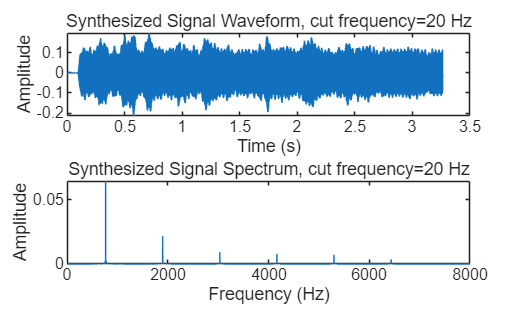


filename = sprintf('Task4_LPF_cut_freq%d.wav', LPF_cut_freq);
audiowrite(filename, y_20, fs);

figure;
subplot(2,1,1);
plot(t, y_20);
title(sprintf('Synthesized Signal Waveform, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y_20);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

LPF_cut_freq = 50

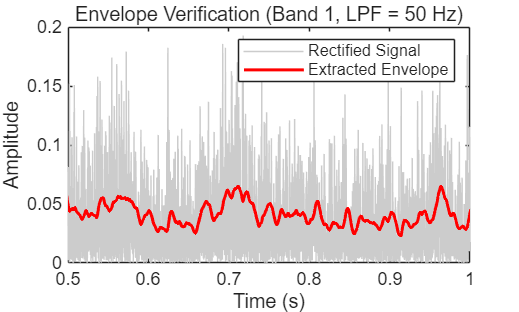

LPF_cut_freq = 50;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2));

y_sum = zeros(1, length(y));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y_band = filter(B, A, y);
    y_band_abs = abs(y_band);
    y_envelope = filter(b0, a0, y_band_abs);

  
    if i == 1 
        figure;
        plot(t, y_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (Band 1, LPF = %d Hz)', LPF_cut_freq));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y_modulated = y_envelope .* sine_wave;
    y_sum = y_sum + y_modulated;
end


e1 = sum(y.^2);
es = sum(y_sum.^2);
y_50 = y_sum * sqrt(e1 / es);
e_final_50 = sum(y_50.^2);
fprintf('能量验证 LPF = 50Hz原始信号能量: %.4f, 归一化后信号能量: %.4f\n', e1, e_final_50);

能量验证 LPF = 50Hz原始信号能量: 152.7444, 归一化后信号能量: 152.7444


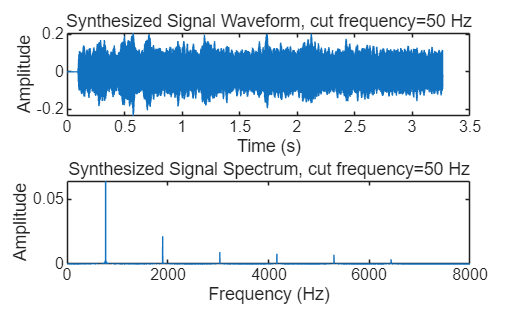


filename = sprintf('Task4_LPF_cut_freq%d.wav', LPF_cut_freq);
audiowrite(filename, y_50, fs);

figure;
subplot(2,1,1);
plot(t, y_50);
title(sprintf('Synthesized Signal Waveform, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y_50);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

LPF_cut_freq = 100

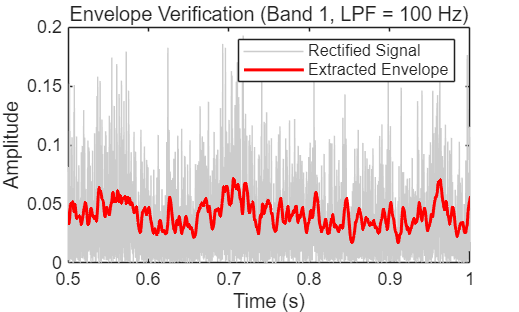

LPF_cut_freq = 100;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2));

y_sum = zeros(1, length(y));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y_band = filter(B, A, y);
    y_band_abs = abs(y_band);
    y_envelope = filter(b0, a0, y_band_abs);

 
    if i == 1 
        figure;
        plot(t, y_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (Band 1, LPF = %d Hz)', LPF_cut_freq));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y_modulated = y_envelope .* sine_wave;
    y_sum = y_sum + y_modulated;
end


e1 = sum(y.^2);
es = sum(y_sum.^2);
y_100 = y_sum * sqrt(e1 / es);
e_final_100 = sum(y_100.^2);
fprintf('能量验证 LPF = 100Hz原始信号能量: %.4f, 归一化后信号能量: %.4f\n', e1, e_final_100);

能量验证 LPF = 100Hz原始信号能量: 152.7444, 归一化后信号能量: 152.7444


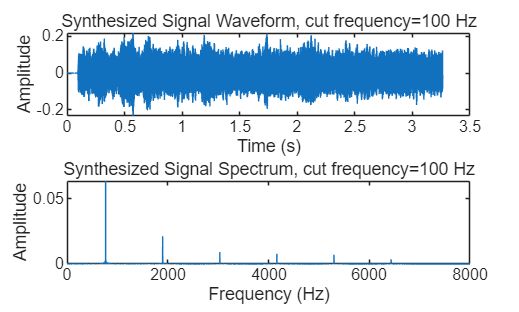


filename = sprintf('Task4_LPF_cut_freq%d.wav', LPF_cut_freq);
audiowrite(filename, y_100, fs);

figure;
subplot(2,1,1);
plot(t, y_100);
title(sprintf('Synthesized Signal Waveform, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y_100);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

LPF_cut_freq = 400

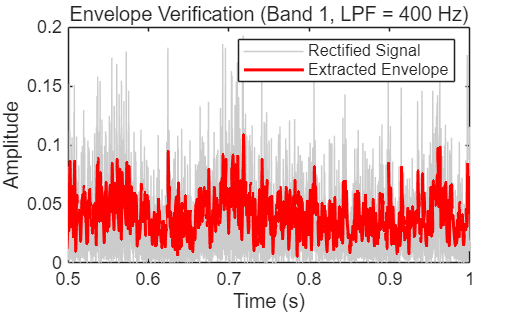

LPF_cut_freq = 400;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2));

y_sum = zeros(1, length(y));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y_band = filter(B, A, y);
    y_band_abs = abs(y_band);
    y_envelope = filter(b0, a0, y_band_abs);

    % --- 补充：400Hz 包络验证图 ---
    if i == 1 
        figure;
        plot(t, y_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (Band 1, LPF = %d Hz)', LPF_cut_freq));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y_modulated = y_envelope .* sine_wave;
    y_sum = y_sum + y_modulated;
end


e1 = sum(y.^2);
es = sum(y_sum.^2);
y_400 = y_sum * sqrt(e1 / es);

e_final_400 = sum(y_400.^2);
fprintf('能量验证 LPF = 400Hz原始信号能量: %.4f, 归一化后信号能量: %.4f\n', e1, e_final_400);

能量验证 LPF = 400Hz原始信号能量: 152.7444, 归一化后信号能量: 152.7444


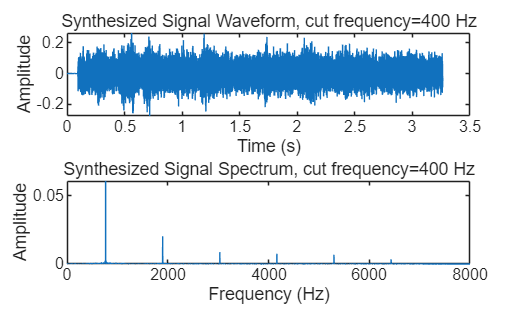


filename = sprintf('Task4_LPF_cut_freq%d.wav', LPF_cut_freq);
audiowrite(filename, y_400, fs);

figure;
subplot(2,1,1);
plot(t, y_400);
title(sprintf('Synthesized Signal Waveform, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y_400);
P = abs(Y_fft/L); %真实振幅 除以L即除以N 求得DTFS
P_single = P(1:floor(L/2)+1); %因为是实信号在频域谱上共轭对称，所以画出一半即可
P_single(2:end-1) = 2*P_single(2:end-1);%因为频域画了一半，所以要把幅度*2 
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);